# Seyed Mohammad Amin Atyabi - 830402014

## Biomedical Signal Processing - Homework 4

# Fantasia Database

## **f1o01**

Directly plot ECG signal from .dat file

According to 250Hz sampling rate, the fist 2500 samples show the first 10 seconds of signal

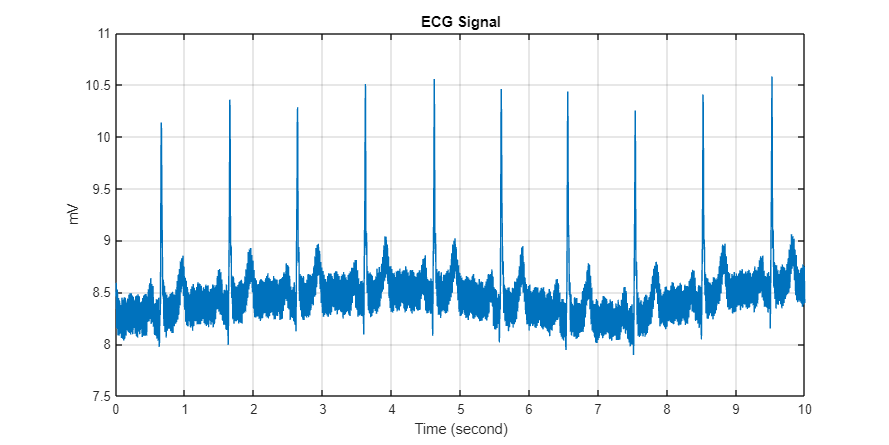

[sig, ~, tm] = rdsamp('Data/f1o-01/f1o01.dat', 2, 2500);
fig = figure(); 
fig.Position(3:4) = [3000, 1500];
plot(tm, sig);
title('ECG Signal');
xlabel('Time (second)');
ylabel('mV');
grid on;

Using *movemean *function of MATLAB we filter (smotoh) our ECG signal.

#### 
$$\begin{array}{l}
K=#\;\mathrm{Points}\\
\mathrm{MovingAverageSignal}=\frac{1}{K}\sum_{i=0}^{K-\;\;1} x_{i-k} 
\end{array}$$


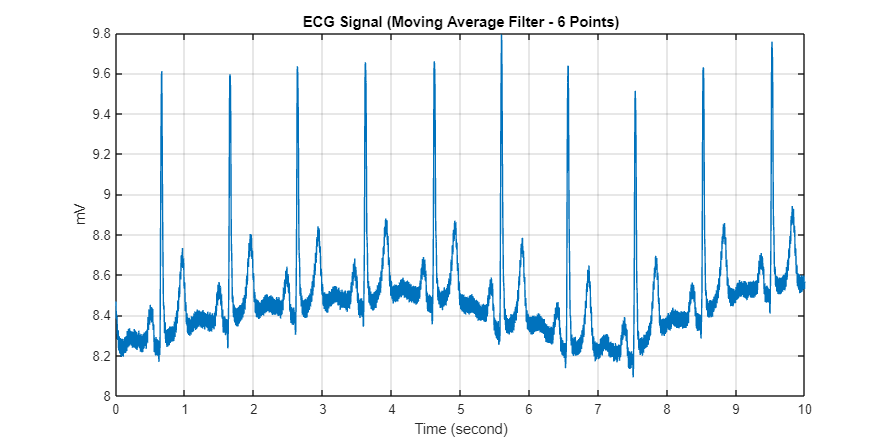

movingAverageFilter = movmean(sig, 6);
plot(tm, movingAverageFilter);
title('ECG Signal (Moving Average Filter - 6 Points)');
xlabel('Time (second)');
ylabel('mV');
grid on;

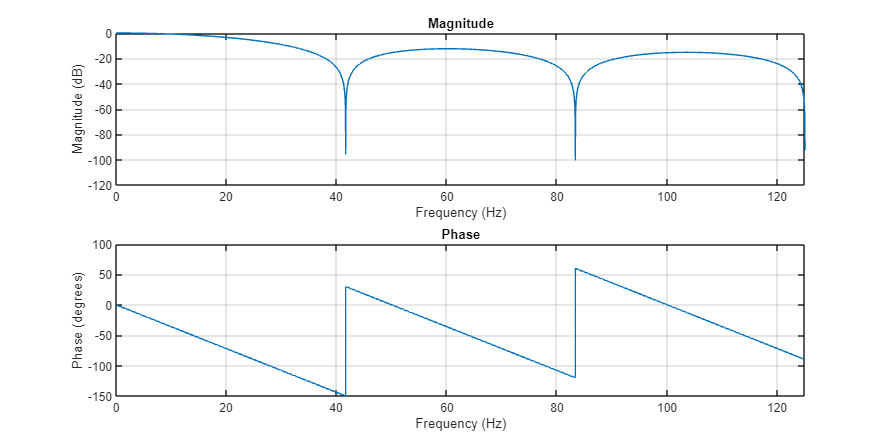

freqz(repelem(1/6, 6), 1, 2^16, 250);

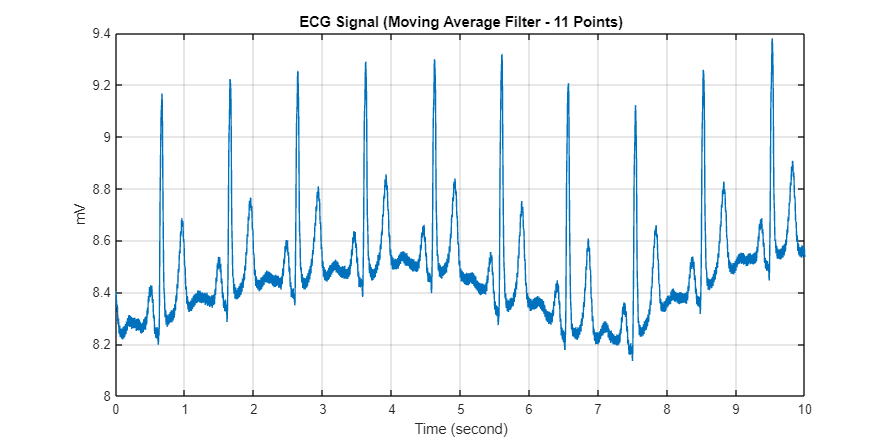

movingAverageFilter = movmean(sig, 11);
plot(tm, movingAverageFilter);
title('ECG Signal (Moving Average Filter - 11 Points)');
xlabel('Time (second)');
ylabel('mV');
grid on;

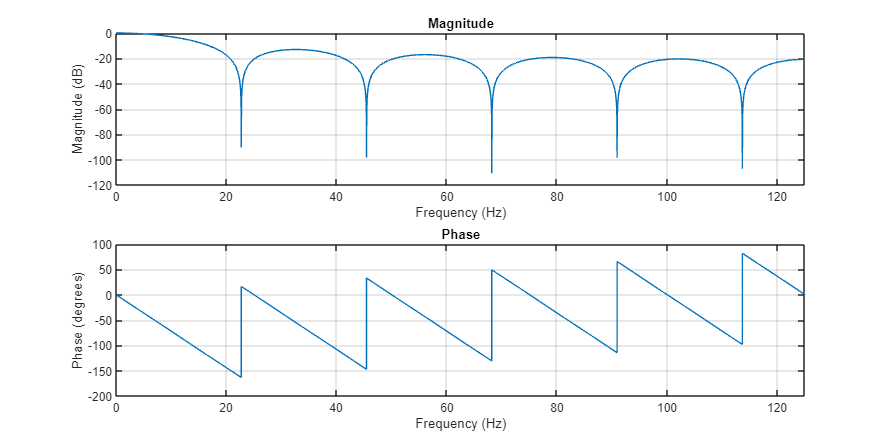

freqz(repelem(1/11, 11), 1, 2^16, 250);

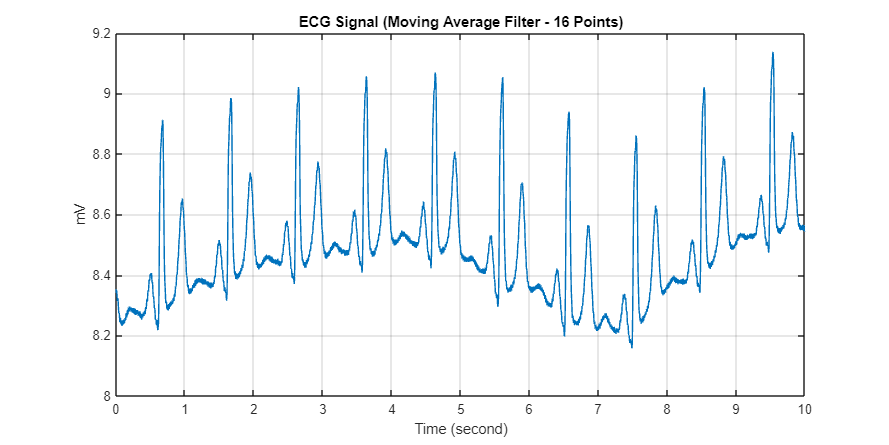

movingAverageFilter = movmean(sig, 16);
plot(tm, movingAverageFilter);
title('ECG Signal (Moving Average Filter - 16 Points)');
xlabel('Time (second)');
ylabel('mV');
grid on;

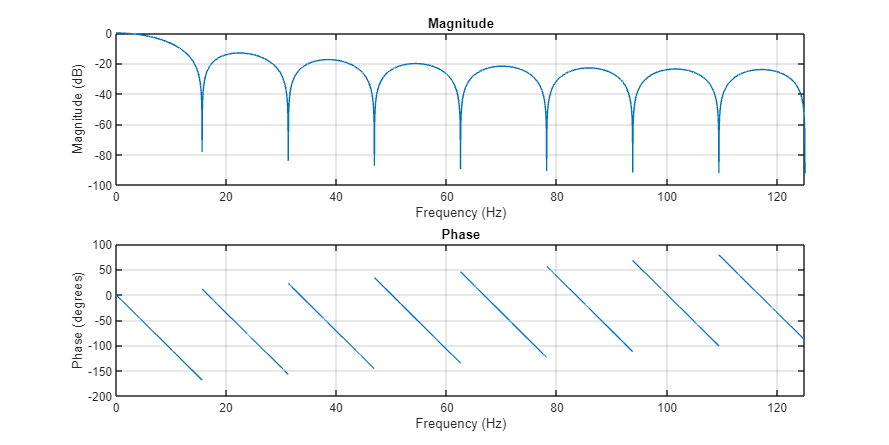

freqz(repelem(1/16, 16), 1, 2^16, 250);

# ECG-ID Database

## **person 1 - rec 14**

Directly plot ECG signal from .dat file

According to 500Hz sampling rate, the fist 5000 samples show the first 10 seconds of signal

[sig, ~, tm] = rdsamp('Data/person 1 - rec 14/rec_14.dat', 1, 5000);

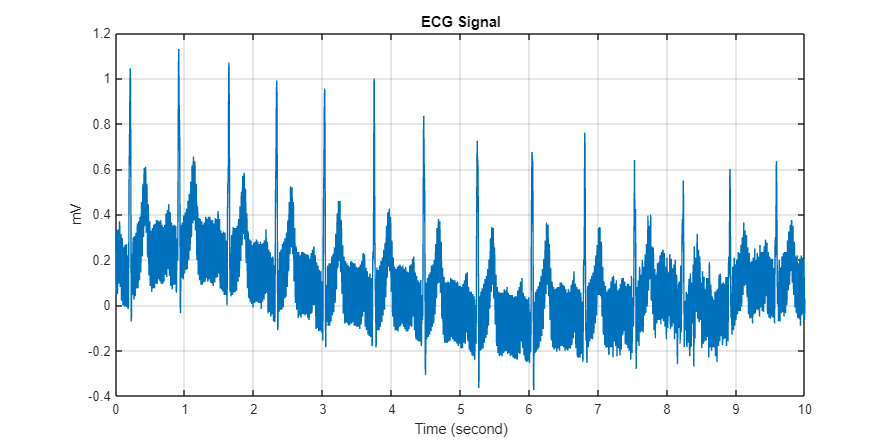

fig = figure(); 
fig.Position(3:4) = [3000, 1500];
plot(tm, sig);
title('ECG Signal');
xlabel('Time (second)');
ylabel('mV');
grid on;

[sig_f, ~, tm] = rdsamp('Data/person 1 - rec 14/rec_14.dat', 2, 5000);

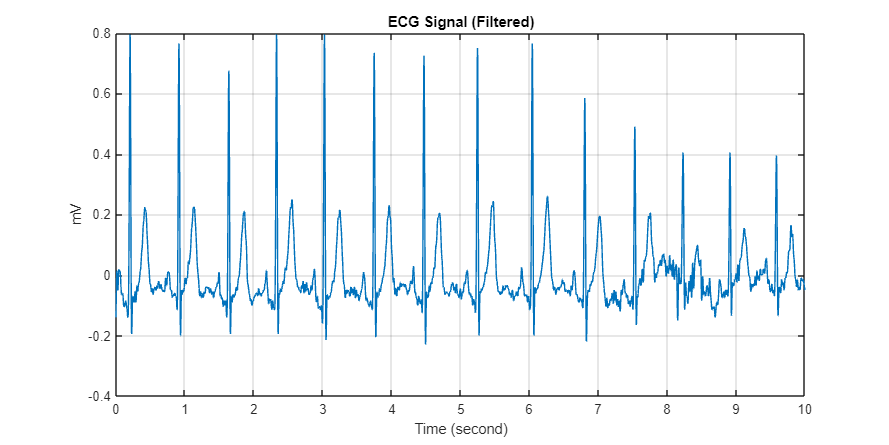

fig = figure(); 
fig.Position(3:4) = [3000, 1500];
plot(tm, sig_f);
title('ECG Signal (Filtered)');
xlabel('Time (second)');
ylabel('mV');
grid on;

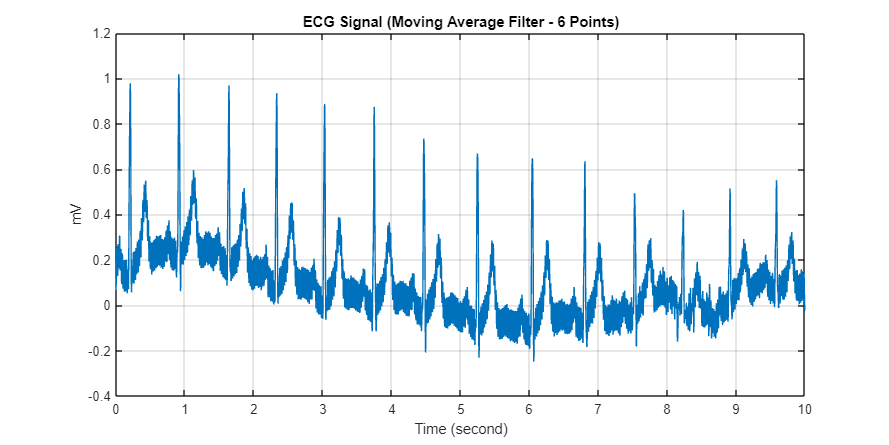

movingAverageFilter = movmean(sig, 6);
plot(tm, movingAverageFilter);
title('ECG Signal (Moving Average Filter - 6 Points)');
xlabel('Time (second)');
ylabel('mV');
grid on;

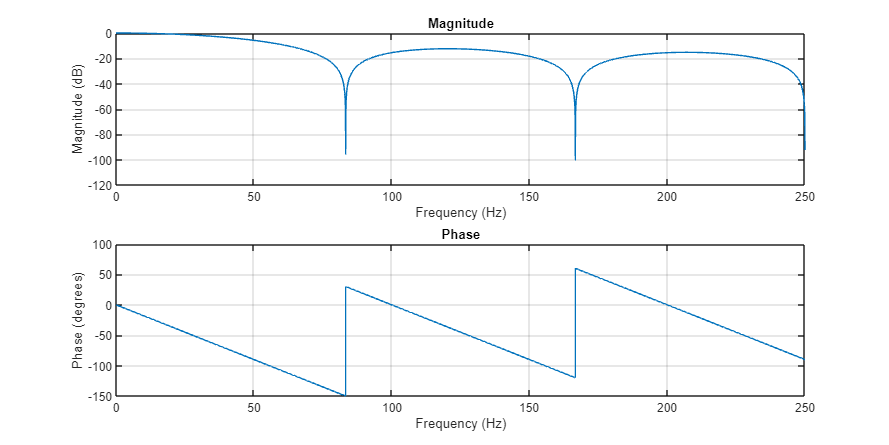

freqz(repelem(1/6, 6), 1, 2^16, 500);

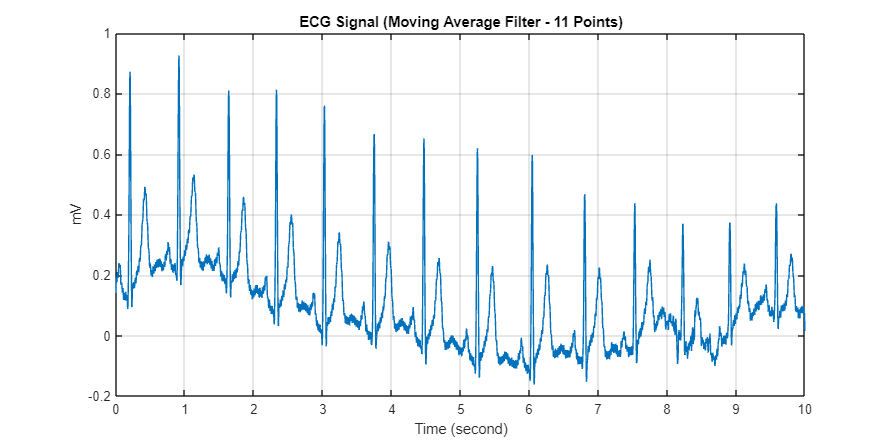

movingAverageFilter = movmean(sig, 11);
plot(tm, movingAverageFilter);
title('ECG Signal (Moving Average Filter - 11 Points)');
xlabel('Time (second)');
ylabel('mV');
grid on;

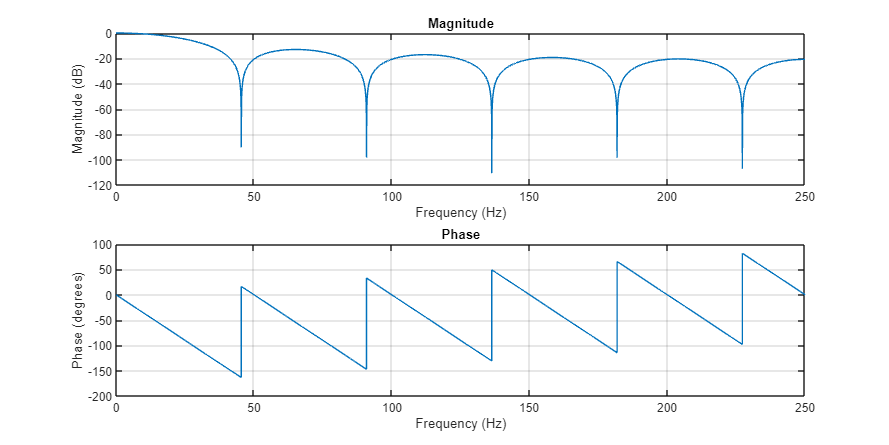

freqz(repelem(1/11, 11), 1, 2^16, 500);

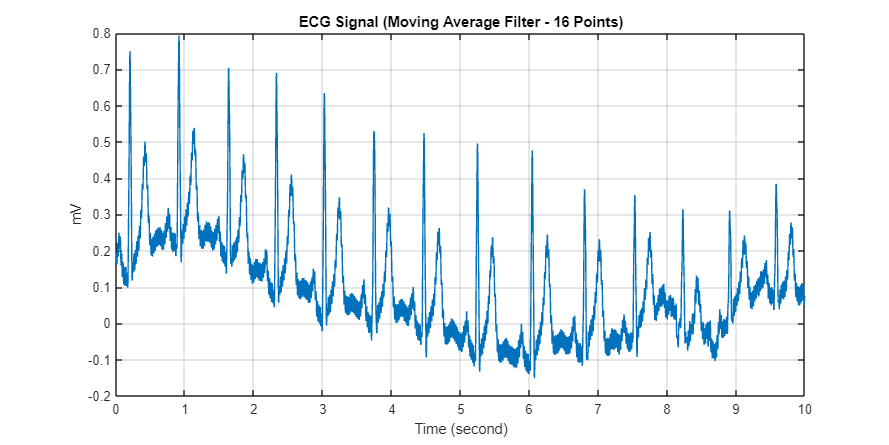

movingAverageFilter = movmean(sig, 16);
plot(tm, movingAverageFilter);
title('ECG Signal (Moving Average Filter - 16 Points)');
xlabel('Time (second)');
ylabel('mV');
grid on;

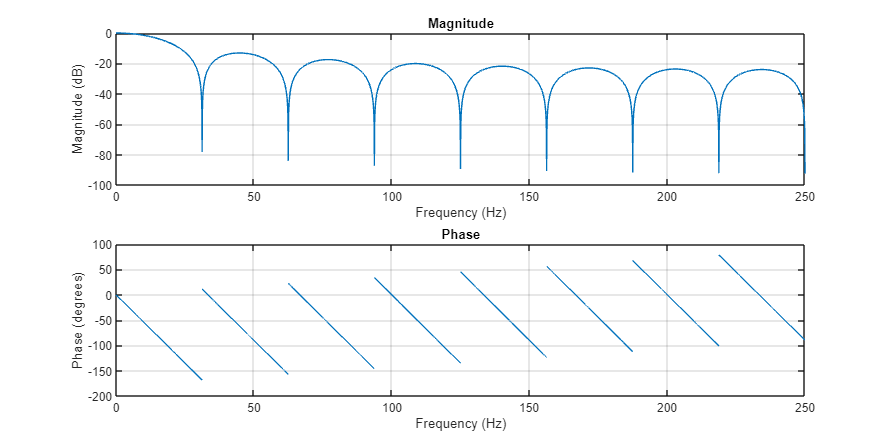

freqz(repelem(1/16, 16), 1, 2^16, 500);